Checkpoint 5.1

Range 0:

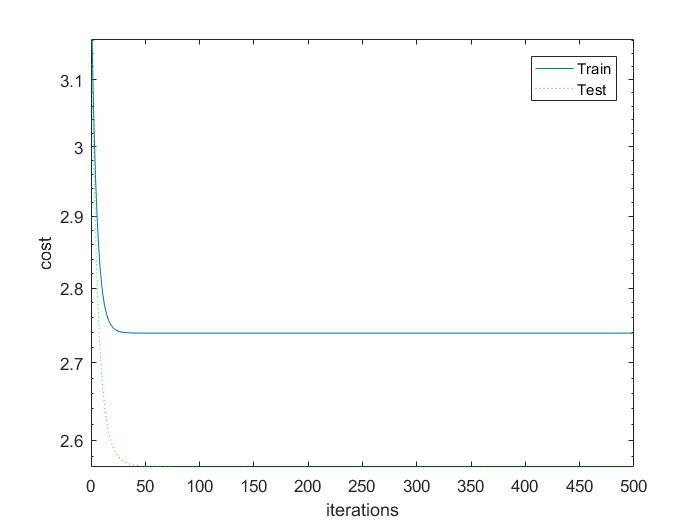

What we can see here is that when the weights are initiallized to 0 the net is learning slow and then stops at one value, which would be the local minima. When we look at the final weights we can see that none of the weights have actually changed but the weight for bias for the output layer. When we look at the equation 8 (zn0 is equal to 1) we can see that it actually makes sense and mathematically none of the weights but the output bias weight should change. It means that the network learnt the output bias weight (which in fact is the mean value of the output) and will not be learning anymore.

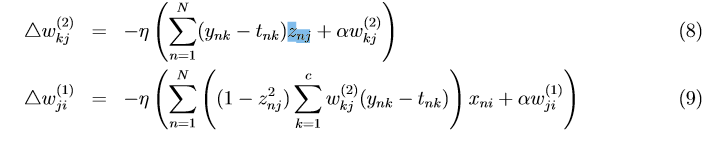

It is worth noting here that the test data has smaller error than the train data. The explanation for that is that the model as we previously showed is learning only the mean value. So if the train data had huge variance and test data had small variance it would be possible that it happens.

Range 0.5:

Here we can see that the notwork achieves way better results as the training progresses and all of the wieghts are being updated.  Additionally we can see that the model actually overfits the training set which can be deducted by looking at train and test errors. There is a point in which traing error is decreasing and the test error is increasing which means that the networks starts to loose to ability to geenralize properly.

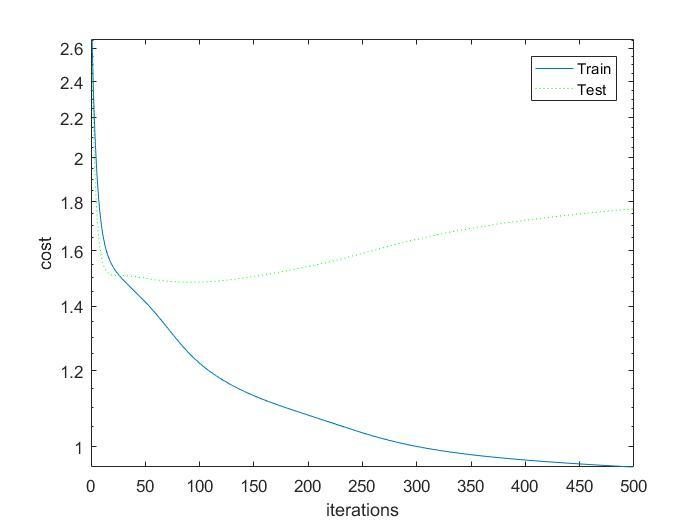

Range 10000:

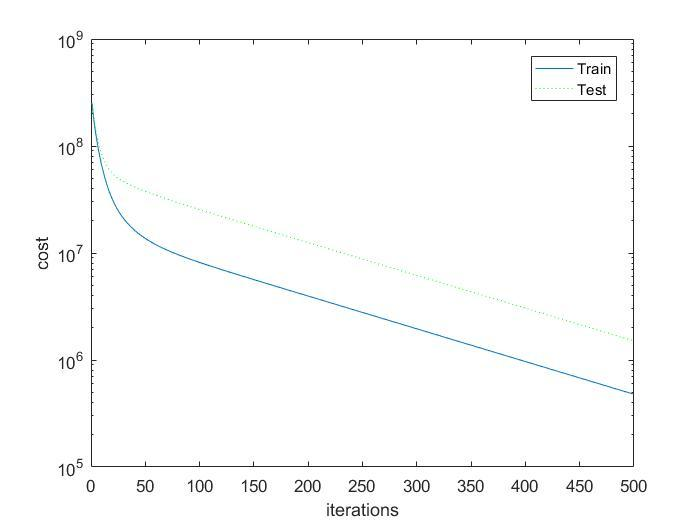

We can see that having large initial weights results in a large initial error of the network this is due to the fact that the output from the network (2nd weights layer) will be large and will be far away from the target value. We can see that the error is decaying but relativly slow this is due to the fact that tanh function is basically a step function for big initial weight. If we look at the following equation 9 we can see that *z will be *either 1 or -1 meaning that the whole sum in equation 9 is reduced to 0 if we dont use weight decay (alpha is 0). Having a weight decay can speed up the process of learning for large weights. The other layer will be learning but it's not enough as we need both of the layers to work properly:

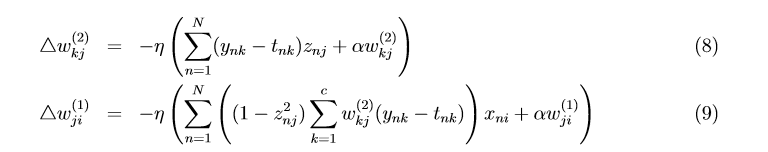

**Checkpoint 5.2**

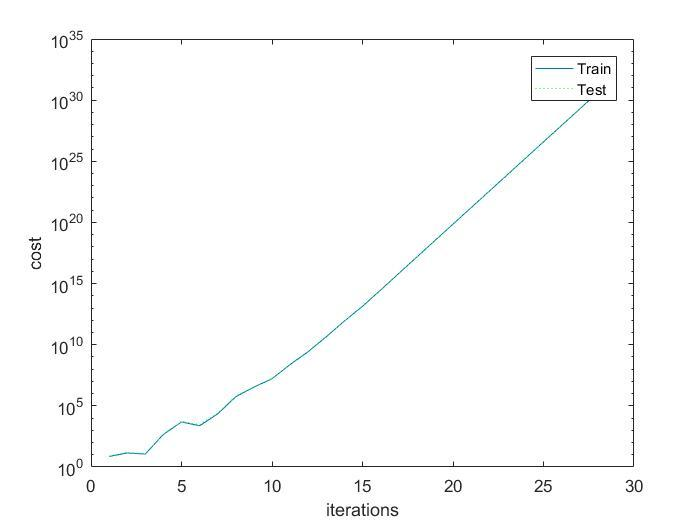

Here we can see a learning rate of 0.02, which results in an unstable model as the jumps between iterations are too large and it never converges.

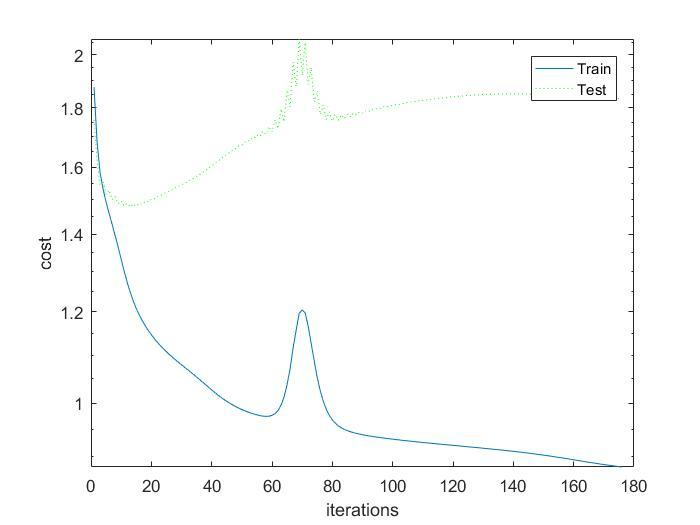

This plot shows the learning with learning rate of 0.007. We can see that it is quickly reducing the cost value but additionally we can see an overshoot at one point.

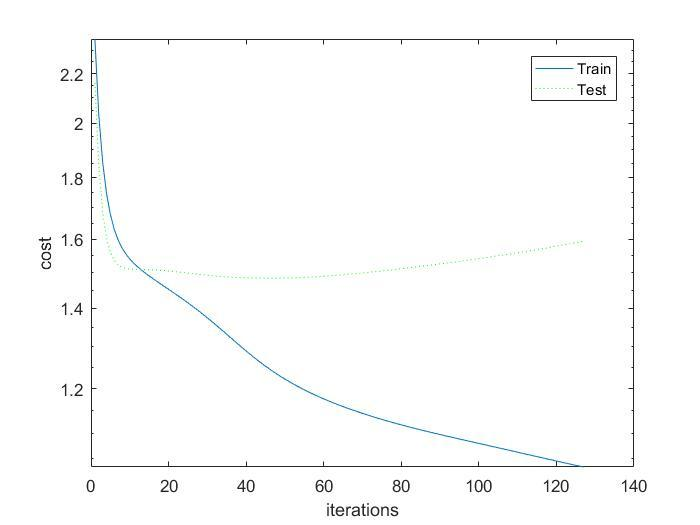

This plot shows learning with 0.002. It seems to have acceptable results as it's not overshooting at any point and we learn very quickly. Basically after 10-20 iterations the test error is not dropping anymore.

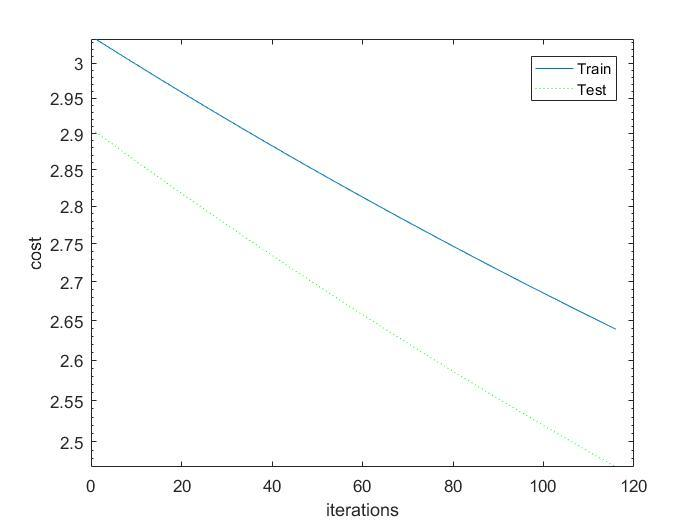

This example shows the learning plot for the very small learning rate of 0.00001. You can see that the network learns very slowly in that case.

Additionally we tried playing with the learning rate in exercise 5b.

**Below learning rate 0.005**

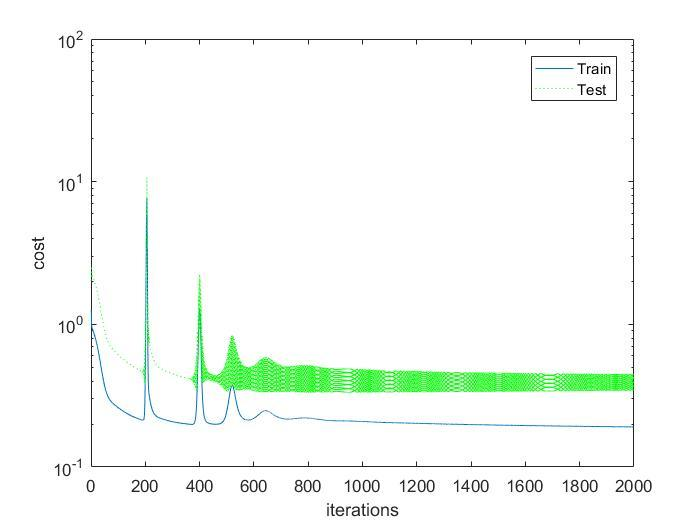

**Below learning rate 0.003**

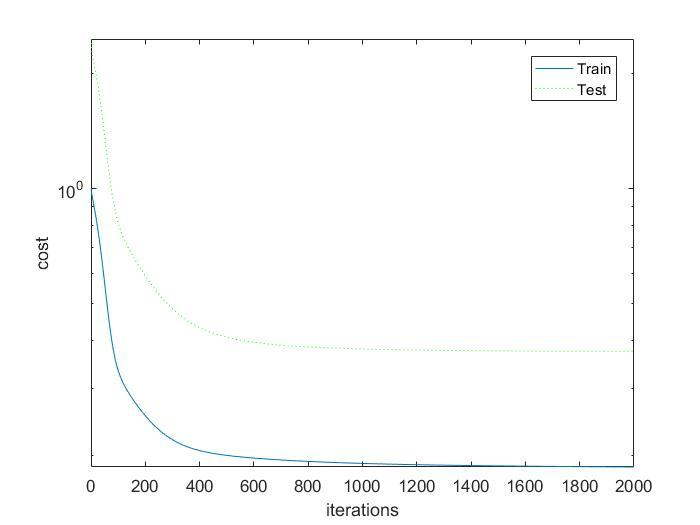

For the exercise 5a, the satisfactory learning rate was selected to be 0.002.

**Checkpoint 5.3**

In this exercise we looked at plots of the gradient norm and  train cost difference. These are values that might allow us to select a stopping criteria, an condition that automatically makes a decision if the training should be stopped.

Train const difference is the difference between cost function in current iteration and cost function in the previous iteration. As the model learns it should be dropping because as we get closer to the minimum it should be learning slower.

Gradient norm is a norm (in this case euclidan length) of the gradient. We expect it to go to zero as the model learns. This is because the point in which all gradients will be zero is a local/global minimum.

The simplest idea would be to put a threshold on the test cost function but the problem is that it's hard to determine a threshold value as the final value depends heavily on the hyperparameter selection (see plots below). This makes us turn to the previously mentioned values which give information about current learning speed.

We can set a threshold on these values to determine when to stop learning. But as we can see on the plots below that the settling value varies significantally dpeending on the hyperparameters. Taking that into consideration it seems that the best stopping criterioin would be stability of the diff and norm gradient values. One solution to get that criterion would be checking for x iterations is the relative change of these signal was bigger than some percantage threshold. Of course this stopping critaria has it's disadvantages as it is possible that the network gets stuck around local minima and is slowly escaping it, this method might stop the training in that case.

Combining any of the metioned criterias might bring even better results and it seems that they might be used exchangably depending on our goal. It seems that if we are able to approximate the satisfying cost function it's worth adding a threshold on that additioanlly to the other mentioned cirterias.

Learning rate 0.009

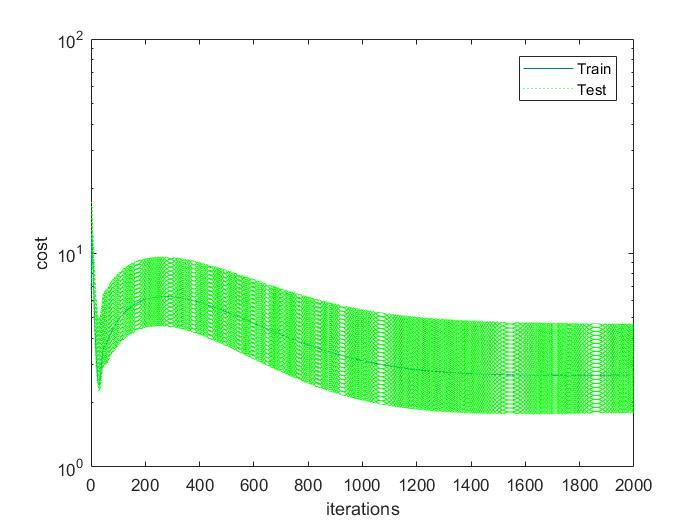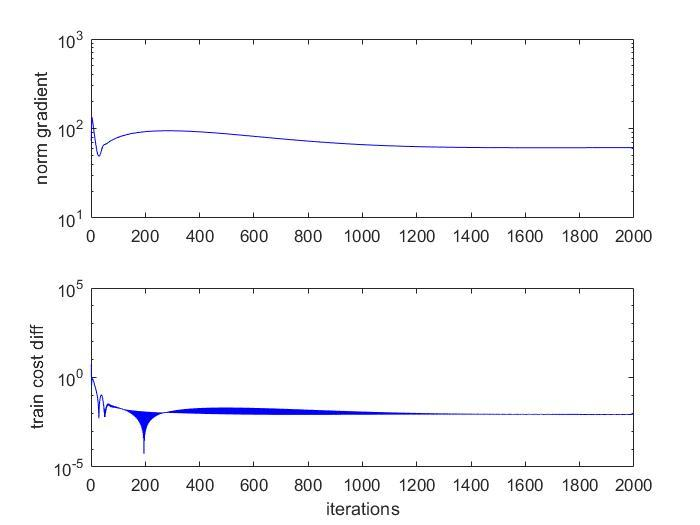

Learning rate 0.005

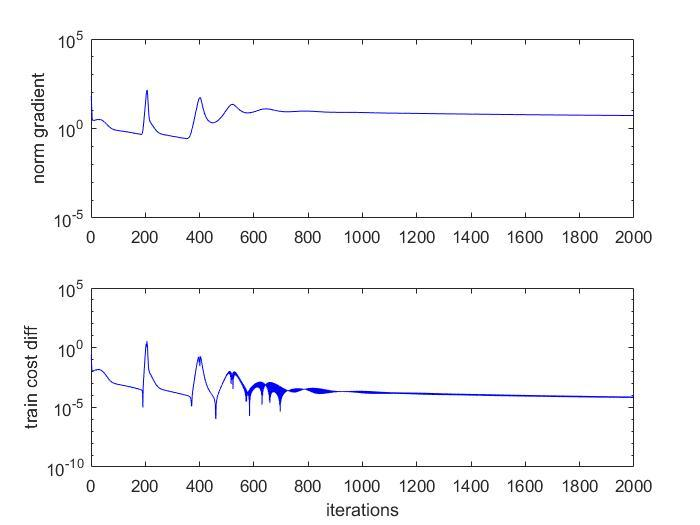

The oscillation on these plots is caused by the solution oscillating around minimum point. As the model was trained on the training data it will be smaller for the training set than for the test set. But the oscillations can be observerd on the both plots.

**Checkpoint 5.4**

Let's start by taking a look at the output graph of the program

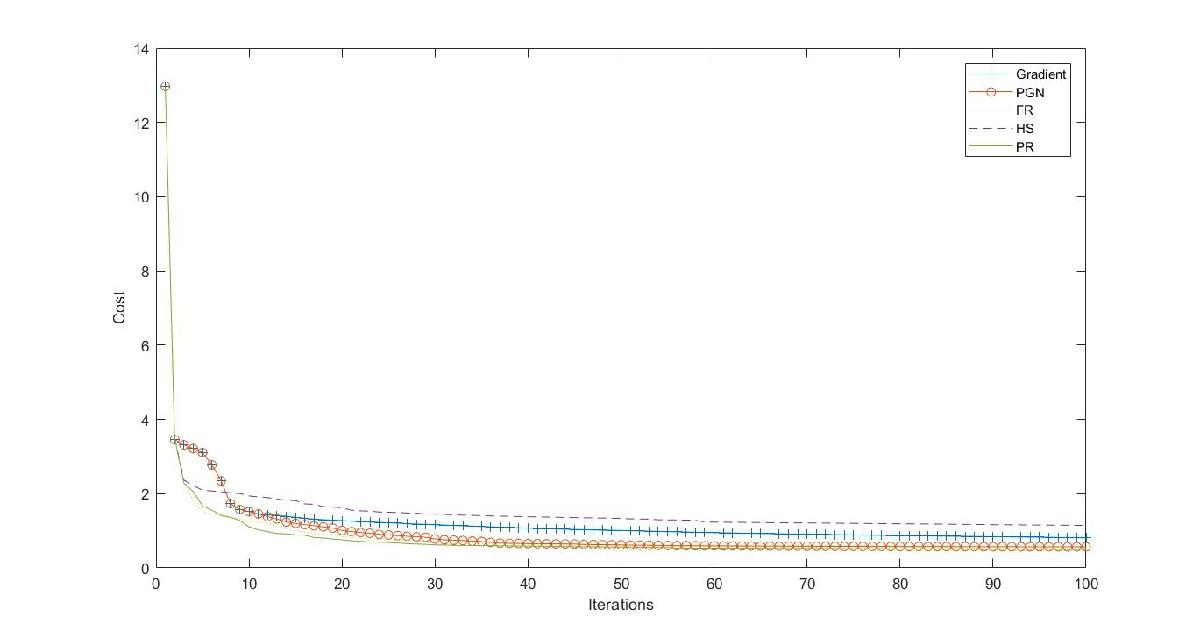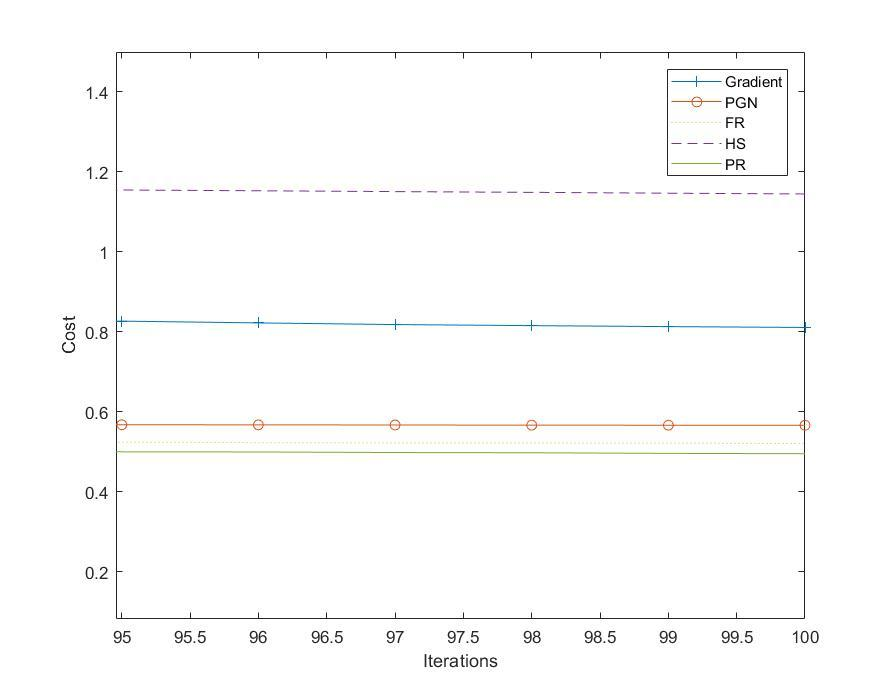

From this graph we can extract two important indicators that defines the performance of an optimization algorithm: Final cost after 100 iterations and speed of convergence. 

Based on the first indicator we see that the algorithm that throws better results is Polak-Ribiere, followed closely by Fletcher-Reeves. The worst result in this case is the one obtained by using  Hestenes-Stiefel. 

The second indicator shows also a really good performance of Polak-Ribiere algorithm, which led us to the conclusion that it is the best algorithm for this datset and neural network. 

However, it is important to highlight that there is a reason why so many algorithms exist and are used, and it is because they work better in different scenarios. For example, we tried to change the weight initialization from 0.5 to 0.9, and we obtained the following final cost results: 

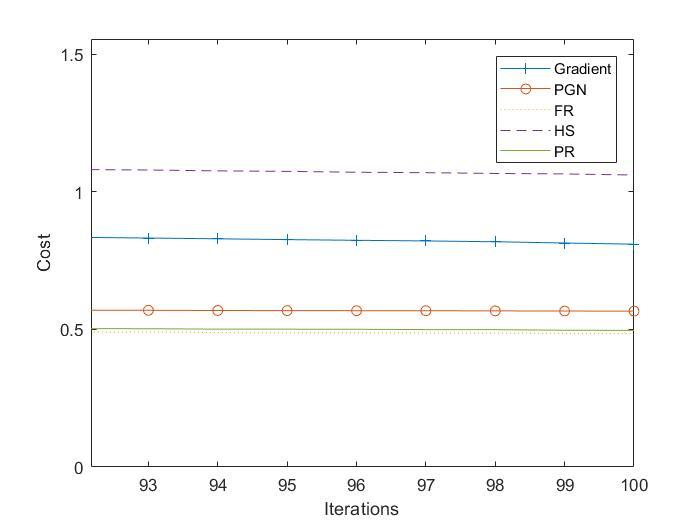

In this case, and just with that subtle change, the FR algorithm achieves slightly better results than the PR algorithm. 

In the case when the network is completely changed, the results are even more different. Let's take now a NN with 5 input neurons and 100 hidden neurons:

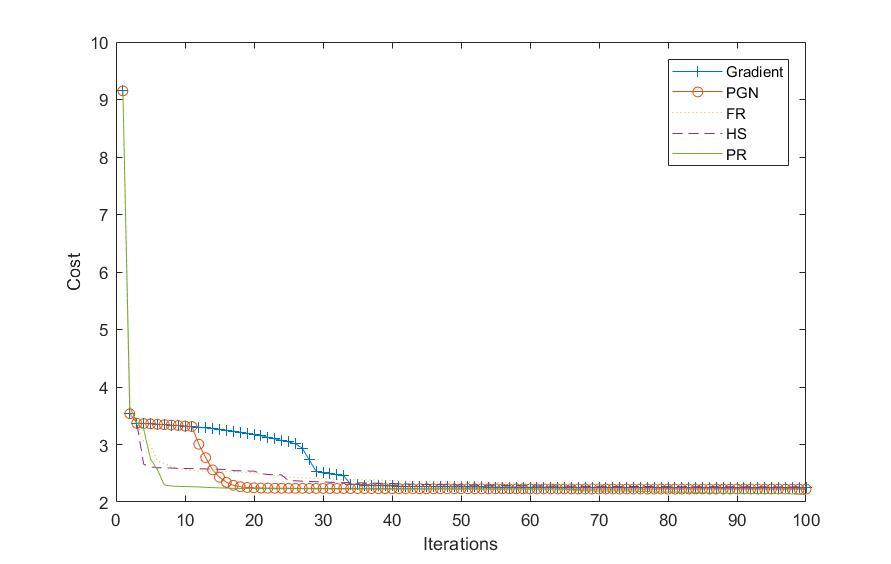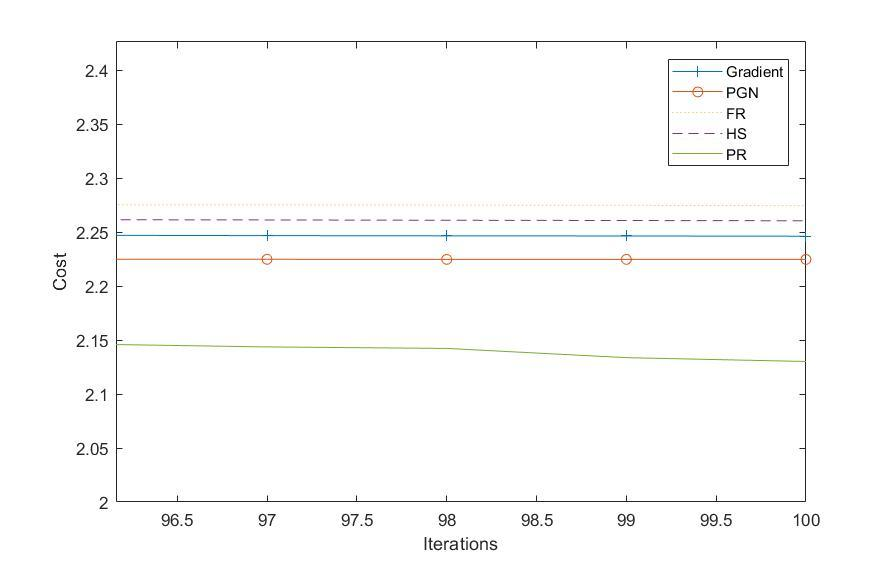

As we can see, the performance of gradient descent in this case is way worse than the one in the previous case. At the same time, if we take a look at the final cost we can see that the FR algorithm, which gave us the best results in the previous case, is giving now the higher cost. 

Thus, we can conclude that there is no method better than another just based on this particular example. With different datasets we would probably obtain different results, so the only solution is to try different algorithms for the particular problem on hand.